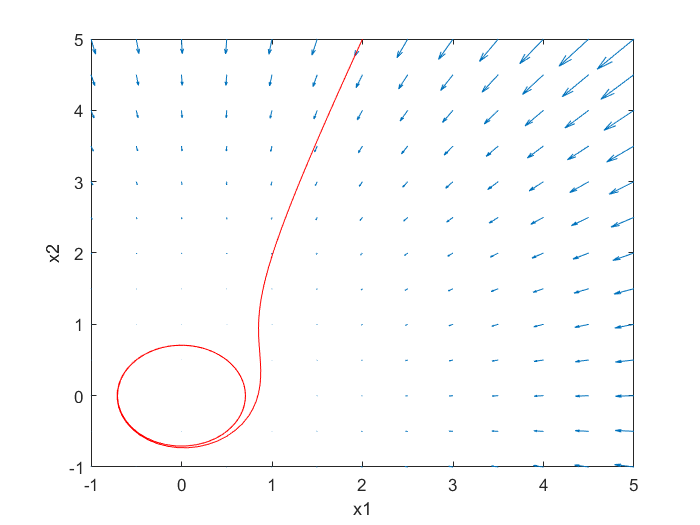

fun_ode = @(t,x) [x(2) + x(1)*(0.5 - x(1).^2 - x(2).^2); -x(1) + x(2)*(0.5 - x(1).^2 - x(2).^2)];

initial_values = [2,5];
step = 0.5;
range = 5;
xspan = -1:step:range;
yspan = -1:step:range;
[x, y] = meshgrid(xspan, yspan);

S = size(x,1);
u = zeros(S^2, 1);
v = zeros(S^2, 1);

counter = 1;
for r=1 : S
    for c=1 : S
        result = fun([xspan(r), yspan(c)]);
        u(counter) = result(1); %x1
        v(counter) = result(2); %x2
        counter = counter+1;
    end
    
end

figure
quiver(x(:), y(:), u,v);
hold on
tspan = [0, 15];
[t, data] = ode45(fun_ode, tspan, initial_values);
plot(data(:,1), data(:,2), 'r');
xlabel("x1");
ylabel("x2");
hold off